1.

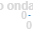

f0 = 1;
k = 10000; %quanto maior mais reto fica
fa = 2 * (k * f0);
a = zeros(1, k+1);
b = zeros(1, k+1);

for i = 1:k
    if mod((i-1), 2) == 0
        b(i) = 0;
    end
    if mod((i-1), 2) ~= 0
        b(i) = 4/((i-1)*pi);
    end
end

%maneira da stora
%    i = 1:2:10;
%    b(2:2:end) = 4./(i* pi)
%dá igual !


[sinal, t] = somaFourier(1 / fa, f0, 4, a, b);

plot(t,sinal);
grid on;
title('Gráfico onda Sinusoidal');
xlabel('Tempo (seg)');
ylabel('x(t)');
axis([0 4 -1.5 1.5]);